S0 = 50; % Initial stock price
sigma = 0.3; % Volatility
K = 52; % Strike price
T = 2; % Time to maturity
r = 0.05; % Risk-free rate
q = 0; % non-dividend-paying
OptionType = 'P';

fprintf('Black-Scholes formula = %.4f\n', BS(S0, K, r, q, sigma, T, OptionType))

Black-Scholes formula = 9.7086


## **I. Standard Error and Number of Trials **

[put_100, se_100, ci_100, st_100] = monte_carlo_put(100, S0, K, T, r, sigma);

Elapsed time is 0.002209 seconds.


[put_10000, se_10000, ci_10000, st_10000] = monte_carlo_put(10000, S0, K, T, r, sigma);
[put_1000000, se_1000000, ci_1000000, st_1000000] = monte_carlo_put(1000000, S0, K, T, r, sigma);


fprintf('NP = 100: Estimated Put Price = %.4f, SE = %.4f, CI = [%.4f, %.4f]\n', put_100, se_100, ci_100(1), ci_100(2));

NP = 100: Estimated Put Price = 7.6252, SE = 1.0170, CI = [5.6318, 9.6186]


fprintf('NP = 10,000: Estimated Put Price = %.4f, SE = %.4f, CI = [%.4f, %.4f]\n', put_10000, se_10000, ci_10000(1), ci_10000(2));

NP = 10,000: Estimated Put Price = 6.7285, SE = 0.0947, CI = [6.5428, 6.9142]


fprintf('NP = 1,000,000: Estimated Put Price = %.4f, SE = %.4f, CI = [%.4f, %.4f]\n', put_1000000, se_1000000, ci_1000000(1), ci_1000000(2));

NP = 1,000,000: Estimated Put Price = 6.7733, SE = 0.0096, CI = [6.7546, 6.7920]


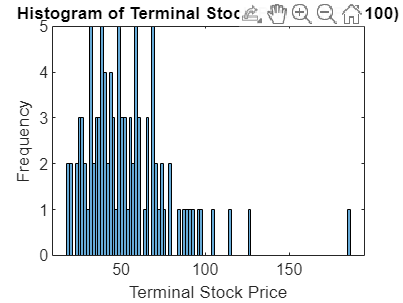


plot_histogram(st_100, 100)

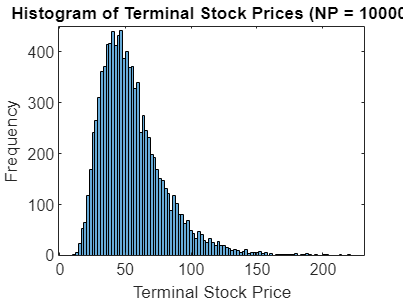

plot_histogram(st_10000, 10000)

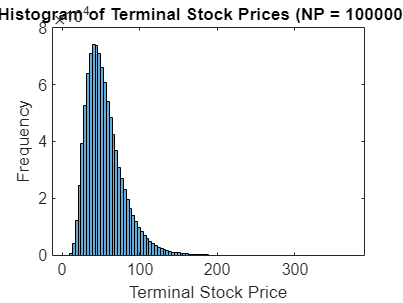

plot_histogram(st_1000000, 1000000)

## II. Standard Deviation of Estimated Option Values

NE = 500;
put_100 = zeros(1, NE);
put_10000 = zeros(1, NE);
put_1000000 = zeros(1, NE);

tic
for n = 1:NE
    [put_100(n), se_100, ci_100, st_100] = monte_carlo_put(100, S0, K, T, r, sigma);
    [put_10000(n), se_100, ci_100, st_100] = monte_carlo_put(10000, S0, K, T, r, sigma);
    [put_1000000(n), se_100, ci_100, st_100] = monte_carlo_put(1000000, S0, K, T, r, sigma);
end
toc

Elapsed time is 5.241104 seconds.


disp(put_100(1:30))

  Columns 1 through 20

    6.3457    6.3406    7.6010    7.1071    7.9687    5.3804    7.3349    6.5243    6.1813    6.5946    6.5825    8.1582    6.9837    5.9675    5.5654    5.6494    7.1602    6.4400    6.8716    7.4304

  Columns 21 through 30

    7.2016    5.3727    5.7824    7.3406    5.7198    6.3823    7.4298    5.2518    7.1823    6.8560



disp(put_10000(1:30))

  Columns 1 through 20

    6.8215    6.6537    6.7599    6.6651    6.6155    6.6763    6.7511    6.6979    6.7926    6.8271    6.7873    6.7081    6.7177    6.7873    6.7311    6.9604    6.8940    6.7033    6.7543    6.7323

  Columns 21 through 30

    6.7737    6.7117    6.8272    6.8188    6.7928    6.6863    6.7394    6.7996    6.7307    6.7784



disp(put_1000000(1:30))

  Columns 1 through 20

    6.7588    6.7578    6.7461    6.7709    6.7480    6.7701    6.7692    6.7542    6.7638    6.7646    6.7644    6.7594    6.7512    6.7596    6.7626    6.7581    6.7586    6.7702    6.7714    6.7549

  Columns 21 through 30

    6.7484    6.7576    6.7677    6.7562    6.7684    6.7645    6.7554    6.7665    6.7537    6.7547




fprintf("NP = %d, Mean = %.4f, STD = %.4f", 100, mean(put_100), std(put_100))

NP = 100, Mean = 6.7343, STD = 0.9105

fprintf("NP = %d, Mean = %.4f, STD = %.4f", 10000, mean(put_10000), std(put_10000))

NP = 10000, Mean = 6.7555, STD = 0.0873

fprintf("NP = %d, Mean = %.4f, STD = %.4f", 1000000, mean(put_1000000), std(put_1000000))

NP = 1000000, Mean = 6.7596, STD = 0.0088

function [put_price, std_error, ci, ST] = monte_carlo_put(NP, S0, K, T, r, sigma)
    
    % Simulate paths and calculate payoffs

    ST = S0 * exp((r - sigma^2 / 2) * T + sigma * sqrt(T) * randn(1, NP));
    payoffs = max(K - ST, 0); % Payoff for put option
    
    % Estimate the option price
    discounted_payoff = mean(exp(-r * T) * payoffs);
    put_price = discounted_payoff;
    
    % Standard error and confidence interval
    std_error = std(payoffs) / sqrt(NP);
    ci = [put_price - 1.96 * std_error, put_price + 1.96 * std_error];
end
function plot_histogram(ST, NP)
    figure;
    histogram(ST, 100);
    title(['Histogram of Terminal Stock Prices (NP = ' num2str(NP) ')']);
    xlabel('Terminal Stock Price');
    ylabel('Frequency');
end